clear; clc; close all;
%globals
D0 = 100; %00
D1 = 150; %01
D2 = 200; %10
D3 = 250; %11

DELAYS = [D0, D1, D2, D3];   % Symbol 0=00, 1=01, 2=10, 3=11

%echo amp
ALPHA = 0.7;

%segment length
SEGMENT_LEN = 512; %samples read in by buffer

%window size
WIN = 2; %samples before and after in cepstrum

%paths
M4A_FILE    = 'stego_compressed.m4a';
WAV_DECODED = 'stego_decompressed.wav';


%load host signal
%[host, fs] = audioread('test.wav'); %in these cases we use 44.1k because it has highest capacity

% record cover signal
fprintf('Recording COVER audio...\n')

Recording COVER audio...


host = record_audio_for_n_seconds(5);

Recording...
Done


fs   = 44100;

% convert to mono
if size(host, 2) > 1
    host = mean(host, 2);
end

% record secret message
fprintf('Recording SECRET audio...\n')

Recording SECRET audio...


secret = record_audio_for_n_seconds(5); 

Recording...
Done


if size(secret, 2) > 1
    secret = mean(secret, 2);
end

% compress secret into bitstream
message = compressAudioToBitstream(secret, fs);

%%% MESSAGE SECTION REPLACE WITH WHAT WE WANT TO USE. NEEDS TO BEA
%%% BITSTREAM LIKE WHAT IS GIVEN HERE
%some tools to turn certain files into bitstreams are in my repo

%this is is our capacity with the given params. Symbols are two bit with
%this 4 delay system
max_symbols = floor(numel(host) / SEGMENT_LEN);
max_bits    = max_symbols * 2;
%i kind of hope we dont need to do FEC but we could


%message = [1 0 1 1 0 0 1 0 0 0 1 1 1 1 0 0 0 1 1 0 1 0 0 1]; % arbitrary bits
message = message(1 : floor(length(message)/2)*2);  % trim to even length
n_symbols = length(message) / 2;

if length(message) > max_bits
    fprintf("The message is too big")
end

The message is too big


% Pack bit pairs into symbol indices 0-3
symbols = zeros(1, n_symbols);
for k = 1 : n_symbols
    b1 = message(2*k - 1);
    b2 = message(2*k);
    symbols(k) = b1*2 + b2;
end

%-----encode-----
stego = host; %copy for cover signal

for k = 1 : n_symbols
    seg_start = (k-1) * SEGMENT_LEN + 1;
    seg_end   = seg_start + SEGMENT_LEN - 1;

    %case where message is too long
    if seg_end > numel(host)
        break;
    end

    segment = host(seg_start : seg_end);
    delay   = DELAYS(symbols(k) + 1);   % +1 for matlab 1-indexing

    echo_sig = zeros(SEGMENT_LEN, 1);
    echo_sig(delay+1 : end) = ALPHA * segment(1 : end-delay);

    stego(seg_start : seg_end) = segment + echo_sig;
end

stego = stego / max(abs(stego));

%%%----Compression/Decompression-----
% compress
audiowrite(M4A_FILE, stego, fs, 'BitRate', 128); %bitrate is in kbps

%decompress to m4a
[stego_m4a, fs_m4a] = audioread(M4A_FILE);
%stego_m4a = stego; %check and see if the cepstrum looks better

%this can be a bug sometimes, resampling will probably kill us but i wont
%do math to prove it
if fs_m4a ~= fs
    stego_m4a = resample(stego_m4a, fs, fs_m4a);
    fprintf("warning: resampling")
end

audiowrite(WAV_DECODED, stego_m4a, fs);

%%----Decode----

%probably want to get a symbol for everything and assume the message is
%always being...
decoded_symbols = zeros(1, n_symbols);
for k = 1 : n_symbols
    seg_start = (k-1) * SEGMENT_LEN + 1;
    seg_end = min(seg_start + SEGMENT_LEN - 1, numel(stego_m4a));

    if seg_end - seg_start + 1 < SEGMENT_LEN / 2
        decoded_symbols(k) = -1;
        continue;
    end

    segment = stego_m4a(seg_start : seg_end);
    N = numel(segment);
    cepstrum = real(ifft(log(abs(fft(segment, N)) + eps)));

    scores = zeros(4, 1);
    for s = 1:4
        d = DELAYS(s);
        scores(s) = sum(abs(cepstrum( max(1,d-WIN) : min(N,d+WIN) )));
    end

    [~, best]          = max(scores);
    decoded_symbols(k) = best - 1;
end

% Unpack symbols to bits
decoded = zeros(1, numel(message));
for k = 1 : n_symbols
    if decoded_symbols(k) == -1
        decoded(2*k-1 : 2*k) = -1;
    else
        decoded(2*k-1) = floor(decoded_symbols(k) / 2);
        decoded(2*k)   = mod(decoded_symbols(k), 2);
    end
end

%%----check performance----

valid  = decoded ~= -1;
errors = sum(message(valid) ~= decoded(valid));
ber    = errors / sum(valid);

fprintf('Original : [%s]\n', num2str(message));

Original : [0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  1  1  1  1  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  1  0  0  1  1  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  0  0  0  0  0  0  0  0  0  0  0  0  0  0  1  0  0  0  0  0  0  0  0  0  0  0  0  1  0  0  0  1  0  0  1  1  1  1  1  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0

fprintf('Decoded  : [%s]\n', num2str(decoded(valid)));

Decoded  : [0  0  0  0  0  0  1  1  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  1  1  1  1  0  0  1  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  1  0  0  1  1  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  0  1  0  0  0  0  0  0  0  0  0  0  0  0  1  0  0  0  0  0  0  0  0  0  0  0  0  1  0  0  0  1  1  0  1  1  1  1  1  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  1  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0

fprintf('Bit errors: %d / %d  (BER = %.3f)\n', errors, sum(valid), ber);

Bit errors: 11 / 862  (BER = 0.013)


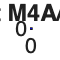



%%plotting

figure;
seg1     = stego_m4a(1 : min(SEGMENT_LEN, numel(stego_m4a)));
cep1     = real(ifft(log(abs(fft(seg1)) + eps)));
plot(0:numel(cep1)-1, cep1, 'k', 'LineWidth', 0.8); hold on;
for s = 1:4
    xline(DELAYS(s), ['b' '--']);
end

xlim([0, SEGMENT_LEN]);
title(sprintf('Cepstrum of Segment 1 (post M4A/AAC) — Symbol: %d (bits: %s)', ...
      decoded_symbols(1), num2str(message(1:2))));
xlabel('Quefrency (samples)'); ylabel('Cepstral Amplitude');